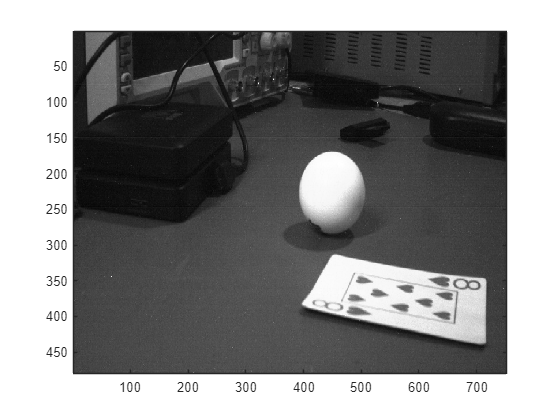

Frame_1 = imread(uigetfile('.png''.jpg'));
formated_frame_1 = rgb2gray(Frame_1);
colormap gray
imagesc(formated_frame_1)


cols = 752

cols = 752

rows = 480

rows = 480


w = 100

w = 100

h = 100

h = 100


binary = zeros(rows,cols);
for x = 1:cols
    for y = 1:rows
        if (formated_frame_1(y,x) > 150)
            binary(y,x) = 1;
        end
    end
end
imshow(formated_frame_1)
[center, radius] = imfindcircles(formated_frame_1,[30 80])

center =   449.1268  224.8199


radius = 55.9369

%plot(viscircles(center, radius, 'Color', 'red'))
hold on
viscircles(center, radius, 'Color', 'red')

ans =   Group with properties:

    Children: [2×1 Line]
     Visible: on
     HitTest: on

  Show all properties


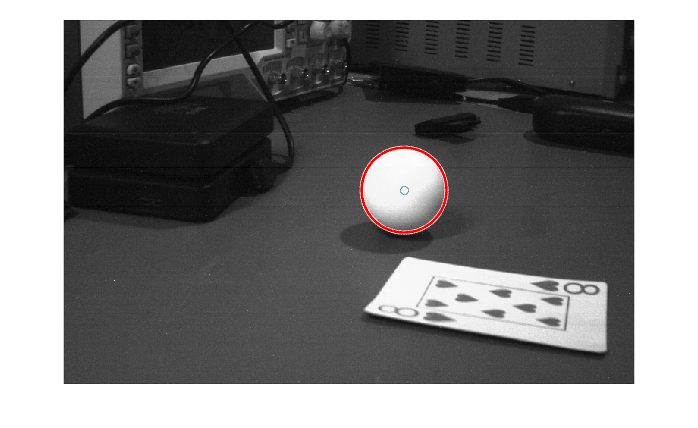

scatter(center(1), center(2))